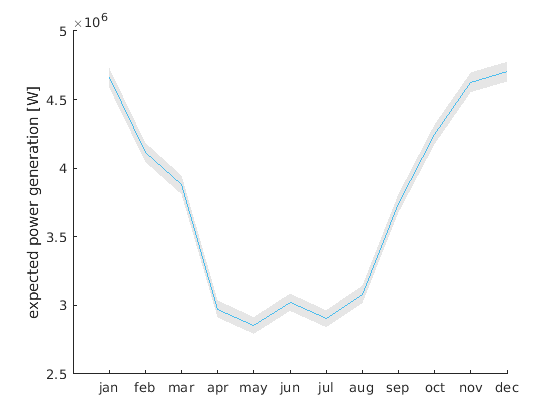

clear;
load powercurve_V164;

% 2(a)
lambdas = [10.6 9.7 9.2 8.0 7.8 8.1 7.8 8.1 9.1 9.9 10.6 10.6];
ks = [2.0 2.0 2.0 1.9 1.9 1.9 1.9 1.9 2.0 1.9 2.0 2.0];

N = 10000;
devs = [];
taus = [];

for month = 1:length(lambdas)
    draw = wblrnd(lambdas(month), ks(month), N, 1);
    ps = P(draw);
    
    tau_n = mean(ps);
    taus(month) = tau_n;
   
    devs(end+1) = 1.96*std(ps)/sqrt(N); 
end

hold on;
confplot(1:1:12, taus, devs);
xticks([1 2 3 4 5 6 7 8 9 10 11 12]);
xticklabels(["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"]);
ylabel('expected power generation [W]')
hold off;


disp("Mean confidence interval width: " + 2*mean(devs));

Mean confidence interval width: 133993.5602


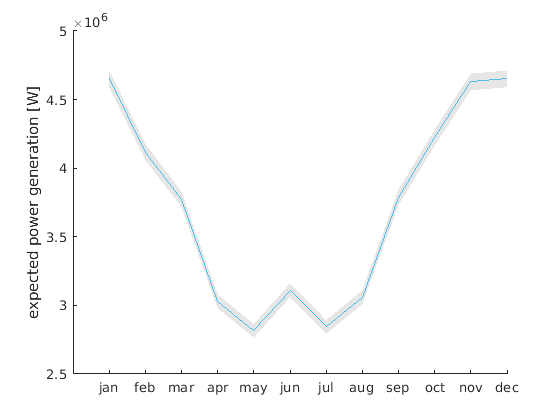

% 2(a) part 2
a = 3.5;
b = 25;

devs_inv = [];
taus_inv = [];

for month = 1:length(lambdas)
    U = rand(N, 1);
    FxA = wblcdf(a, lambdas(month), ks(month));
    FxB = wblcdf(b, lambdas(month), ks(month));
    X = wblinv(U * (FxB - FxA) + FxA, lambdas(month), ks(month));
    
    ps = P(X) * (FxB - FxA);
    
    tau_n = mean(ps);
    taus_inv(end+1) = tau_n;
   
    devs_inv(end+1) = 1.96*std(ps)/sqrt(N); 
end

clf;
hold on;
confplot(1:1:12, taus_inv, devs_inv);
xticks([1 2 3 4 5 6 7 8 9 10 11 12]);
xticklabels(["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"]);
ylabel('expected power generation [W]')
hold off;


disp("Mean confidence interval length: " + 2*mean(devs_inv));

Mean confidence interval length: 110746.105


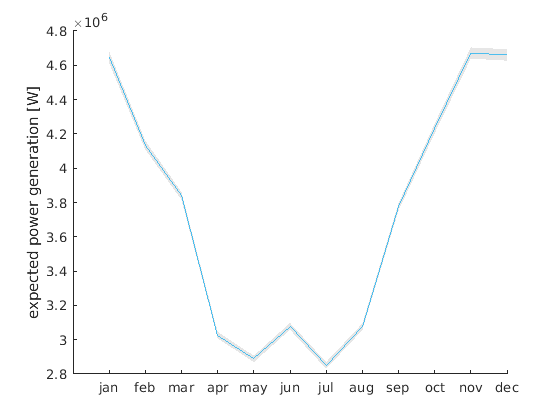

% 2(b)
devs_cv = [];
taus_cv = [];

for month = 1:length(lambdas)
    draw = wblrnd(lambdas(month), ks(month), N, 1);
    ps = P(draw);

    m = lambdas(month) * gamma(1+(1/ks(month)));
    beta = -cov([ps, draw])./var(draw);
    z = ps + beta(1, 2) * (draw - m);

    tau_n = mean(z);
    taus_cv(month) = tau_n;
   
    devs_cv(end+1) = 1.96*std(z)/sqrt(N); 
end

clf;
hold on;
confplot(1:1:12, taus_cv, devs_cv);
xticks([1 2 3 4 5 6 7 8 9 10 11 12]);
xticklabels(["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"]);
ylabel('expected power generation [W]')
hold off;


disp("Mean confidence interval width: " + 2*mean(devs_cv));

Mean confidence interval width: 49310.2881


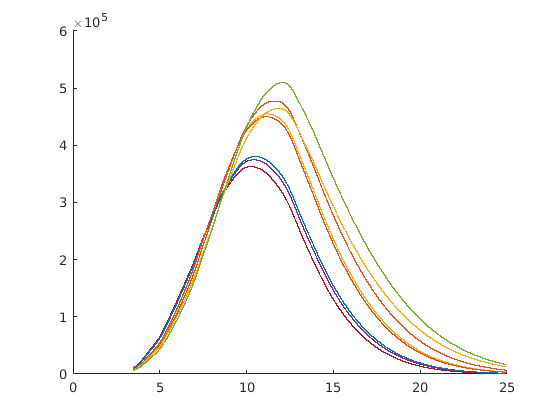

% 2(c) importance sampling
devs_is = [];
taus_is = [];
xs = linspace(3.5, 25, N);

figure;
hold on;
for month = 1:length(lambdas)
    f = @(x) wblpdf(x, lambdas(month), ks(month));
    plot(xs, P(xs).*f(xs)');
end
hold off;

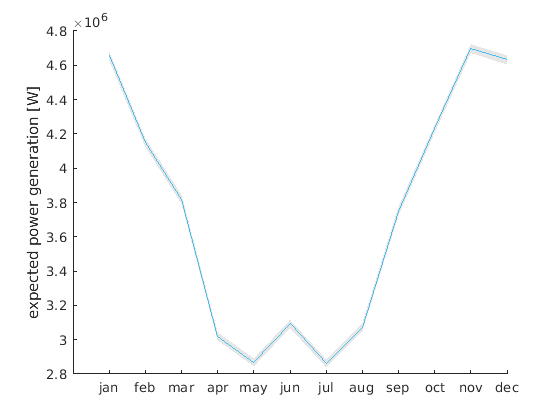

%title('$\phi (x)f(x)$','Interpreter','latex')

for month = 1:length(lambdas)
    f = @(x) wblpdf(x, lambdas(month), ks(month));
    ys = P(xs).*f(xs)';
    [argval, argmax] = max(ys); % mu is the argmax
    mu = xs(argmax);
    
%     % experiment to find sigma
%     figure;
%     for sigma = 1:0.5:10
%         draw = normrnd(mu, sigma, 1, N);
%         g = @(x) normpdf(x, mu, sigma);
%         target = @(x) (f(x).*P(x)') ./ g(x);
%         Y = target(draw);
%     
%         tau_n = mean(Y);
%         taus_is(end+1) = tau_n;
%         devs_is(end+1) = 2*1.96*std(Y)/sqrt(N);
%     end
%     plot(1:0.5:10, devs_is, '*');
%     ylabel('interval width');
%     xlabel('sigma');
%     
%     break;
    
    sigma = 4.5;
    
    draw = normrnd(mu, sigma, 1, N);
    g = @(x) normpdf(x, mu, sigma);
    target = @(x) (f(x).*P(x)') ./ g(x);
    Y = target(draw);
    
    tau_n = mean(Y);
    taus_is(end+1) = tau_n;
    devs_is(end+1) = 1.96*std(Y)/sqrt(N);
end

figure;
hold on;
confplot(1:1:12, taus_is, devs_is);
xticks([1 2 3 4 5 6 7 8 9 10 11 12]);
xticklabels(["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"]);
ylabel('expected power generation [W]')
hold off;


disp("Mean confidence interval width: " + 2*mean(devs_is));

Mean confidence interval width: 49519.9635


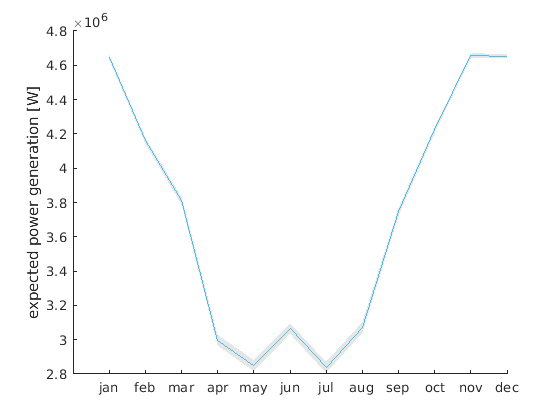

%2(d) antithetic sampling
devs_as = [];
taus_as = [];

for month = 1:length(lambdas)
    XX = rand(N/2, 1);
    V_1 = P(wblinv(XX, lambdas(month), ks(month)));
    V_2 = P(wblinv(1 - XX, lambdas(month), ks(month)));
    W = (V_1 + V_2) / 2;
    
    tau_n = mean(W);
    taus_as(month) = tau_n;
   
    devs_as(end+1) = 1.96*std(W)/sqrt(N / 2); 
end

clf;
hold on;
confplot(1:1:12, taus_as, devs_as);
xticks([1 2 3 4 5 6 7 8 9 10 11 12]);
xticklabels(["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"]);
ylabel('expected power generation [W]')
hold off;


disp("Mean confidence interval width: " + 2*mean(devs_as));

Mean confidence interval width: 46488.728


% 2(e) probability of getting power
months = ["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"];
f = @(lambda, k) exp(-(3.5/lambda)^k) - exp(-(25/lambda)^k);
p = [];

for month = 1:length(lambdas)
    p(end+1) = f(lambdas(month), ks(month));
    % Using crude MC
    disp("Probability that turbine delivers power in " + months(month) + ": " + p(end));
end

Probability that turbine delivers power in jan: 0.89287
Probability that turbine delivers power in feb: 0.87662
Probability that turbine delivers power in mar: 0.86463
Probability that turbine delivers power in apr: 0.81212
Probability that turbine delivers power in may: 0.8039
Probability that turbine delivers power in jun: 0.81603
Probability that turbine delivers power in jul: 0.8039
Probability that turbine delivers power in aug: 0.81603
Probability that turbine delivers power in sep: 0.86196
Probability that turbine delivers power in oct: 0.86751
Probability that turbine delivers power in nov: 0.89287
Probability that turbine delivers power in dec: 0.89287


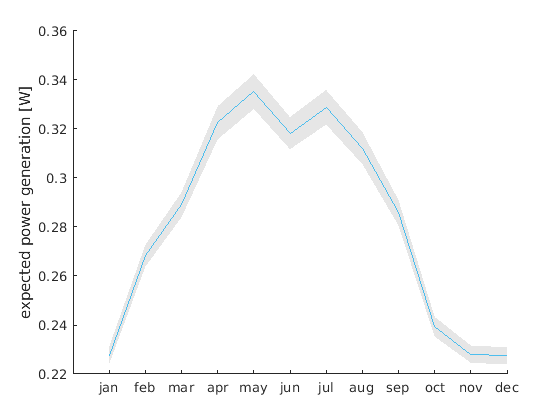

% 2(f)

% 2(f) average power coefficient
devs_apc = [];
taus_apc = [];
interval_apc = ones(12, 3);

rho = 1.225; % air density, 1.225 at sea level
d = 164; % rotor diameter, 164m for a Vestas V164
m = 3;
P_tot = @(x) 1/2 * rho * pi * d^2/4 * gamma(1 + m / ks(x))*lambdas(x)^m;

for month = 1:length(lambdas)
    draw = wblrnd(lambdas(month), ks(month), N, 1);
    ps = P(draw);
    ps_tot = P_tot(month);

    % Testa med antithetic sampling här om du vill, men det ger typ samma
    % resultat.
    %XX = rand(N/2, 1);
    %V_1 = P(wblinv(XX, lambdas(month), ks(month))); % Förstår inte helt varför vi måste använda wblinv?
    %V_2 = P(wblinv(1 - XX, lambdas(month), ks(month)));
    %W = (V_1 + V_2) / 2;
    
    tau_n = mean(ps)/ps_tot;
    taus_apc(month) = tau_n;

    devs_apc(end+1) = 1.96*std(ps./ps_tot)/sqrt(N);
    interval_apc(month, 1) = tau_n - 1.96*std(ps./ps_tot)/sqrt(N);
    interval_apc(month, 2) = tau_n + 1.96*std(ps./ps_tot)/sqrt(N);
    interval_apc(month, 3) = tau_n;
end

clf;
hold on;
confplot(1:1:12, taus_apc, devs_apc);
xticks([1 2 3 4 5 6 7 8 9 10 11 12]);
xticklabels(["jan" "feb" "mar" "apr" "may" "jun" "jul" "aug" "sep" "oct" "nov" "dec"]);
ylabel('expected power generation [W]')
hold off;

disp("Mean confidence interval width: " + 2*mean(devs_apc));

Mean confidence interval width: 0.010565


sympref('FloatingPointOutput',1);
latex_table_apc = latex(sym(interval_apc));

% 2(g)

disp("Capacity factor: " + mean(taus)/9500000);

Capacity factor: 0.3931


disp("Availability factor: " + mean(p));

Availability factor: 0.85011


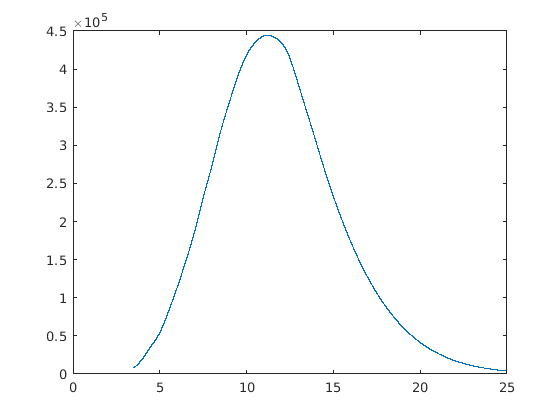

% 3(a)

lambda = 9.13;
k = 1.96;
alpha = 0.638;
p = 3;
q = 1.5;

pdf = @(x) wblpdf(x, lambda, k);
cdf = @(x) wblcdf(x, lambda, k);

biPdf = @(x, y) pdf(x).*pdf(y).*(1+alpha*(1-cdf(x).^p).^(q-1).*(1-cdf(y).^p).^(q-1).*((cdf(x).^p).*(1+p*q)-1).*((cdf(y).^p).*(1+p*q)-1));
biCdf = @(x, y) cdf(x).*cdf(y).*(1+alpha.*(1-cdf(x).^p).^q).*(1-(1-cdf(y).^p).^q);

xs = linspace(3.5, 25, N);
ys = P(xs).*pdf(xs)';
plot(xs, ys);

[argval, argmax] = max(ys); % mu is the argmax
mu = xs(argmax);

% % experiment to find sigma
% n_devs_is = [];
% figure;
% for sigma = 1:0.5:10
%     draw = normrnd(mu, sigma, 1, N);
%     g = @(x) normpdf(x, mu, sigma);
%     target = @(x) (pdf(x).*P(x)') ./ g(x);
%     Y = target(draw);
%     n_devs_is(end+1) = 2*1.96*std(Y)/sqrt(N);
% end
% plot(1:0.5:10, n_devs_is, '*');
% ylabel('interval width');
% xlabel('sigma');

sigma = 4;

draw = normrnd(mu, sigma, 1, N);
g = @(x) normpdf(x, mu, sigma);
target = @(x) (pdf(x).*P(x)') ./ g(x);
Y = target(draw);
tau_n = 2*mean(Y)

tau_n = 7.5615e+06

% 3(b)

mu = [11.187 11.187];
rho = 0.5021;
sigma = [16 rho*16; rho*16 16];
omega = @(x, y) (P(x).*P(y)) .* biPdf(x, y) ./ mvnpdf([x y], mu, sigma);

draw = mvnrnd(mu, sigma, N);
X = draw(:, 1);
Y = draw(:, 2);

c = mean(omega(X, Y), 'all') - (7.5176e06/2)^2

c = 6.8157e+12

% 3(c)

cov = 6.575 * 10^12;
V1 = wblrnd(lambda, k, N, 1);
V2 = wblrnd(lambda, k, N, 1);
p1 = P(V1);
p2 = P(V2);
var = var(p1) + var(p2) + 2*cov;
disp("Variance: " + var)

Variance: 37496578821973


sd = sqrt(var);
disp("Standard Deviation: " + sd)

Standard Deviation: 6123445.0126


% 3(d)
N = 10000;

draw = mvnrnd(mu, sigma, N);
X = draw(:, 1);
Y = draw(:, 2);
P1 = P(X);
P2 = P(Y);

draw = mvnrnd(mu, sigma, N);
sigma = [25 rho*25; rho*25 25];
X1 = draw(:, 1);
Y1 = draw(:, 2);
P11 = P(X1);
P21 = P(Y1);

above = mean(((P1+P2)>9.5*10^6) .* (biPdf(X, Y) ./ mvnpdf([X Y], mu, sigma)))

above = 0.4321

below = mean(((P11+P21)<9.5*10^6) .* (biPdf(X1, Y1) ./ mvnpdf([X1 Y1], mu, sigma)))

below = 0.5234

tot = above + below

tot = 0.9555


above_ci = 1.96*std((P1+P2)>9.5*10^6)/sqrt(N)

above_ci = 0.0088

below_ci = 1.96*std((P1+P2)<9.5*10^6)/sqrt(N)

below_ci = 0.0087